**SIMULATIONS FOR THE ASSIGNMENT-6 QUESTION-2**

**Consider the signal x(t) = exp(-t)sin(t)**

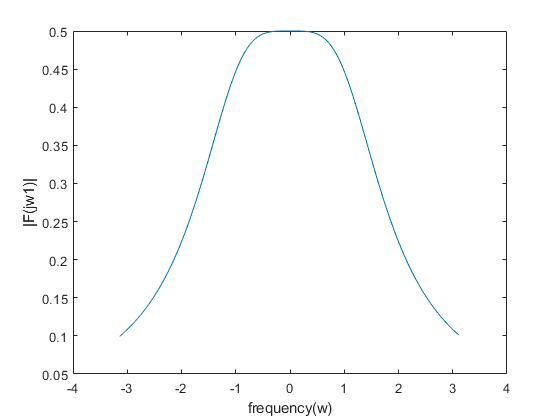

w = -pi:0.05:pi;
Fjw1 = 1./(1+((1+(i*w)).^2));
figure;
plot(w,abs(Fjw1))
xlabel('frequency(w)')
ylabel('|F(jw1)|')

Plotting the magnitude of the fourier transform

Now for the same time domain signal using laplace transform

Sweeping alpha and omega and plotting the magnitude of laplace transform

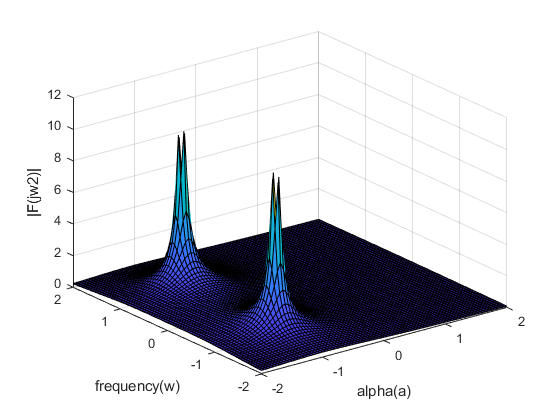

alpha = -2:0.05:2;
omega = -2:0.05:2;
[xa,xw] = meshgrid(alpha,omega);
Fjw2 = 1./(1+((1+ xa + (i*xw)).^2));
figure;
surf(xa,xw,abs(Fjw2));
xlabel('alpha(a)')
ylabel('frequency(w)')
zlabel('|F(jw2)|')

We observe from surface plot at \alpha = 0 we observe the shape of curve is same as previous plot

At  \alpha = -1 and \omega = -1 and +1 we observe the delta functions goes to infinity

**Consider the signal x(t) = exp(-2*t)sin(t)**

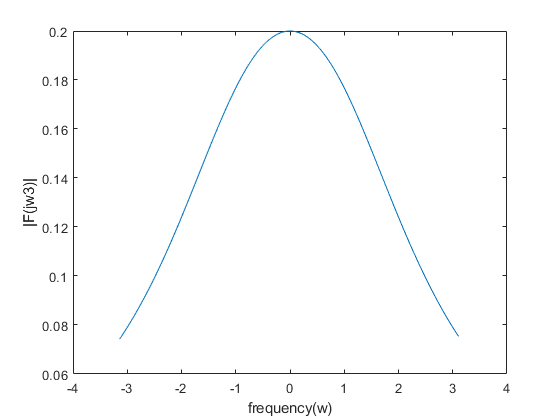

Fjw3 = 1./(1+((2+(i*w)).^2));
figure;
plot(w,abs(Fjw3))
xlabel('frequency(w)')
ylabel('|F(jw3)|')

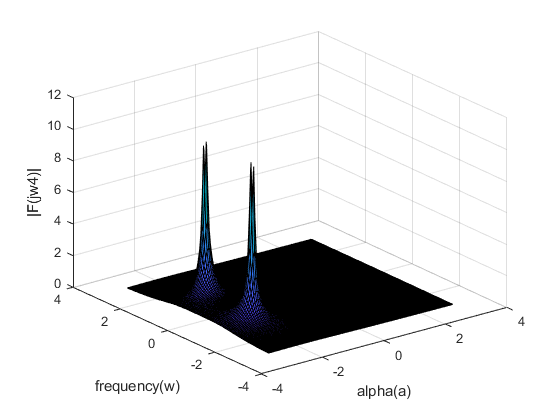

alpha1 = -3:0.05:3;
omega1 = -3:0.05:3;
[xa1,xw1] = meshgrid(alpha1,omega1);
Fjw4 = 1./(1+((2+ xa1 + (i*xw1)).^2));
figure;
surf(xa1,xw1,abs(Fjw4));
xlabel('alpha(a)')
ylabel('frequency(w)')
zlabel('|F(jw4)|')

As from this at \alpha = -2 and \omega = -1 and +1 we observe delta functions goes to infinity

From this the axis \alpha correspons to exponential decay  and axis \omega corresponds to sinusodial functions

Laplace transform of given time domain signal

Using symbolic function and substituting s = alpha + jomega


syms s t a b 
a = laplace(exp(-a*t)*sin(b*t));
disp(a)

$$\frac{b}{{\left(a+s\right)}^{2}+b^{2}}$$